# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 13-Nov-2023 19:38:41

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 3, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ";";

% Specify column names and types
opts.VariableNames = ["Var1", "Var2", "Value"];
opts.SelectedVariableNames = "Value";
opts.VariableTypes = ["string", "string", "double"];

% Specify file level properties
opts.ImportErrorRule = "omitrow";
opts.MissingRule = "omitrow";
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Var1", "Var2"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Var2"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Value", "TrimNonNumeric", true);
opts = setvaropts(opts, "Value", "ThousandsSeparator", ",");

% Import the data
grafanadataexport3 = readtable("C:\Users\marti\Downloads\grafana_data_export (3).csv", opts);

## Convert to output type

grafanadataexport3 = table2array(grafanadataexport3)

grafanadataexport3 =     4.1051
    5.8020
    6.1676
    5.2064
    7.8036
    5.4429
    4.8331
    5.4253
    4.1029
    4.8214


## Clear temporary variables

clear opts

save("61400\gaia_250ms_2min_wind","grafanadataexport3",'-mat');


max(grafanadataexport3)

ans = 11.2075

ans =    121     1


t_wind =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


wind_array =          0    4.1051
    1.0000    5.8020
    2.0000    6.1676
    3.0000    5.2064
    4.0000    7.8036
    5.0000    5.4429
    6.0000    4.8331
    7.0000    5.4253
    8.0000    4.1029
    9.0000    4.8214


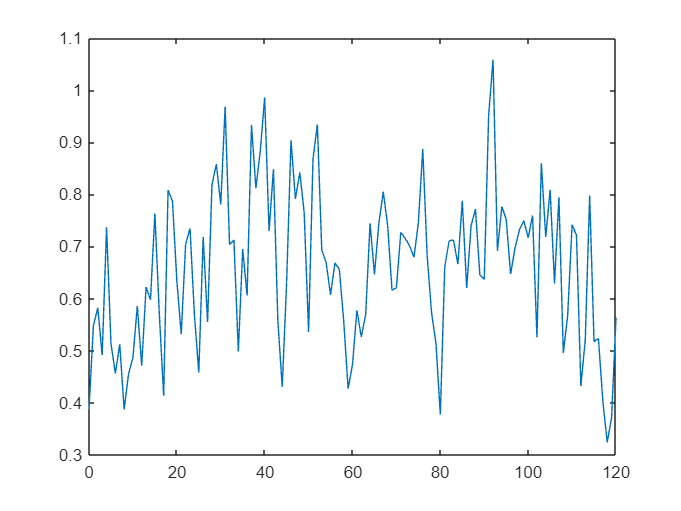

plot(wind_array(:,1),wind_array(:,2)./v_w_n)

% wind initialize
t_init_done = 19

t_init_done = 19

wind_init = v_w_0*v_w_n*ones(1,t_init_done+1)

wind_init =     6.3540    6.3540    6.3540    6.3540    6.3540    6.3540    6.3540    6.3540    6.3540    6.3540    6.3540    6.3540    6.3540    6.3540    6.3540    6.3540    6.3540    6.3540    6.3540    6.3540


t_wind_init = 0:t_init_done

t_wind_init =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19



% repeat sim time times
simtime = 120+t_init_done

simtime = 139

wind_input = grafanadataexport3';
% for i = 1 : simtime
%     wind_input = [wind_input grafanadataexport3'];
% end

size(wind_input)

ans =      1   121


t_wind = linspace(t_init_done+1,simtime,length(wind_input))

t_wind =    20.0000   20.9917   21.9833   22.9750   23.9667   24.9583   25.9500   26.9417   27.9333   28.9250   29.9167   30.9083   31.9000   32.8917   33.8833   34.8750   35.8667   36.8583   37.8500   38.8417   39.8333   40.8250   41.8167   42.8083   43.8000   44.7917   45.7833   46.7750   47.7667   48.7583   49.7500   50.7417   51.7333   52.7250   53.7167   54.7083   55.7000   56.6917   57.6833   58.6750   59.6667   60.6583   61.6500   62.6417   63.6333   64.6250   65.6167   66.6083   67.6000   68.5917



wind_array = [t_wind_init t_wind; wind_init wind_input]'

wind_array =          0    6.3540
    1.0000    6.3540
    2.0000    6.3540
    3.0000    6.3540
    4.0000    6.3540
    5.0000    6.3540
    6.0000    6.3540
    7.0000    6.3540
    8.0000    6.3540
    9.0000    6.3540
